# AME 556 HW 2

Tara Cornwell due Feb 17, 2023

## Q1. Throwing a ball

clear;
global params

m = 0.5;            % kg
g = 9.81;           % m/s^2
params.m = m;
params.g = g;

% Three conditions for initial velocity v0 and drag coeff c
v0(1:3,1:2) = [1 2; 2 1; 1 2];  % m/s
c_list = [0.05; 0.05; 0.5];

tspan=[0; 2]; % simulation time (s)

for ii = 1:3                % 3 initial conditions
    clearvars c

    % Set drag coefficient
    c = c_list(ii);
    params.c = c;

    % Set initial state of the system
    x0=[0;0;v0(ii,1);v0(ii,2)]; % here, x0=[x;y;dx;dy]

    % ODE solver
    [t,x]=ode45(@sys_dynamics_ball,tspan,x0);
    filename = 'HW2_Q1_';
    filename = append(filename,num2str(ii));
    anim(t,x(:,1:2),1/24,filename); % animate the system and save the simulation video

    traj{ii,1}(:,1:4) = x;
    time{:,ii} = t;
    
end

## Plot Q1

% Plot
figure;
hold on;
for ii = 1:3
    plot(traj{ii}(:,1),traj{ii}(:,2),'LineWidth',2)
end
legend({'v_0=[1;2]; c=0.05','v_0=[2;1]; c=0.05','v_0=[1;2]; c=0.5'})
xlabel('x position (m)')
ylabel('y position (m)')
set(gca,'FontName','Arial','FontSize',16)

## Q2. 3-DOF robot arm

clear;
global params
syms theta1 theta2 theta3 a1 a2 a3 m1 m2 m3 dtheta1 dtheta2 dtheta3 ddtheta1 ddtheta2 ddtheta3
assume([theta1 theta2 theta3 a1 a2 a3 m1 m2 m3 dtheta1 dtheta2 dtheta3 ddtheta1 ddtheta2 ddtheta3],'real')

% HOMEWORK 1: Homogeneous transformation matrices
% FROM O0 to O1
    % Rotation about Z0
    R1 = [cos(theta1)   -sin(theta1)   0   0;
          sin(theta1)   cos(theta1)    0   0;
          0                    0       1   0;
          0                    0       0   1];
    R01 = R1(1:3,1:3);

    % Translation up Z
    T1 = [1 0 0 0;
          0 1 0 0;
          0 0 1 a1;
          0 0 0 1];
    
    % Homogeneous transformation matrix H = R*T
    H01 = simplify(R1*T1);
    params.H01 = H01;
    p0 = [0;0;0];       % position of O0 wrt {0}
    p1 = H01(1:3,end);  % position of O1 wrt {0}

% FROM O1 to O2
    % Rotation about Y1
    R2 = [cos(theta2)    0    sin(theta2)    0;
          0              1       0           0;
          -sin(theta2)   0    cos(theta2)    0;
          0              0       0           1];
    R12 = R2(1:3,1:3);
    
    % Translation up X
    T2 = [1 0 0 a2;
          0 1 0 0;
          0 0 1 0;
          0 0 0 1];
    
    % Homogeneous transformation matrix H = R*T
    H12 = simplify(R2*T2);
    params.H12 = H12;
    H02 = simplify(H01*H12);
    params.H02 = H02;
    p2 = H02(1:3,end);  % position of O2 wrt {0}

% FROM O2 to O3
    % Rotation about Y2
    R3 = [cos(theta3)    0    sin(theta3)    0;
          0              1       0           0
          -sin(theta3)   0    cos(theta3)    0;
          0              0       0           1];
    R23 = R3(1:3,1:3);
    
    % Translation up X
    T3 = [1 0 0 a3;
          0 1 0 0;
          0 0 1 0;
          0 0 0 1];

    % Homogeneous transformation matrix H = R*T
    H23 = simplify(R3*T3);
    params.H23 = H23;
    H03 = simplify(H02*H23);
    params.H03 = H03;
    p3 = H03(1:3,end);  % position of O3 wrt {0}

% a) Derive dynamics using E-L eqn:

q = [theta1; theta2; theta3]; % q
dq = [dtheta1; dtheta2; dtheta3]; % q_dot
ddq = [ddtheta1; ddtheta2; ddtheta3]; % q_double_dot
params.q = q;
params.dq = dq;
params.ddq = ddq;

% KINETIC ENERGY
% Link 1
I1 = (1/12)*m1*a1^2;                % moment of inertia about link's center
pc1 = (p0+p1)/2;                    % (O0+O1)/2
v1 = jacobian(pc1,q)*dq;            % x_dot = J(q)*q_dot
w01 = [0;0;dtheta1];                % angular vel wrt {0}
w1n = sqrt(w01(1)^2 + w01(2)^2);    % angular vel perp to link
K1 = 0.5*I1*w1n^2 + 0.5*m1*norm(v1)^2;

% Link 2
I2 = (1/12)*m2*a2^2;                    % moment of inertia about link's center
pc2 = (p1+p2)./2;                       % (O1+O2)/2
v2 = simplify(jacobian(pc2,q)*dq);      % x_dot = J(q)*q_dot
w12 = [0;dtheta2;0];                    % angular vel wrt {1}
w02 = w01 + simplify(R01*w12);          % angular vel wrt {0}
w2b = simplify(transpose(R01*R12)*w02); % angular vel wrt {b}
w2n = sqrt(w2b(2)^2 + w2b(3)^2);        % angular vel perp to link
K2 = simplify(0.5*I2*w2n^2 + 0.5*m2*transpose(v2)*v2);

% Link 3
I3 = (1/12)*m3*a3^2;                        % moment of inertia about link's center
pc3 = (p2+p3)./2;                           % (O2+O3)/2
v3 = simplify(jacobian(pc3,q)*dq);          % x_dot = J(q)*q_dot
w23 = [0;dtheta3;0];                        % angular vel wrt {2}
w03 = w02 + simplify(R01*R12*w23);          % angular vel wrt {0}
w3b = simplify(transpose(R01*R12*R23)*w03); % angular vel wrt {b}
w3n = sqrt(w3b(2)^2 + w3b(3)^2);            % angular vel perp to link
K3 = simplify(0.5*I3*w3n^2 + 0.5*m3*transpose(v3)*v3);

K = K1+K2+K3;

% POTENTIAL ENERGY
g = 9.81; % m/s
% Link 1
P1 = m1*g*pc1(3);

% Link 2
P2 = m2*g*pc2(3);

% Link 3
P3 = m3*g*pc3(3);

% Total potential energy:
P = P1+P2+P3;

% Lagrangian:
L = K - P;

% Euler-Lagrange: d/dt(dL/ddq) - dL/dq = torque

% Link 1
dL_dtheta1 = jacobian(L,theta1);
dL_ddtheta1 = simplify(jacobian(L,dtheta1));

% Link 2
dK_dtheta2 = simplify(jacobian(K,theta2));
dP_dtheta2 = simplify(jacobian(P,theta2));
dL_ddtheta2 = simplify(jacobian(L,dtheta2));

% Link 3
dK_dtheta3 = simplify(jacobian(K,theta3));
dP_dtheta3 = simplify(jacobian(P,theta3));
dL_ddtheta3 = simplify(jacobian(L,dtheta3));


## Q2b) MATLAB function to get D and N

% Custom MATLAB function eom to get D and N
[D,N] = eom(K,P)

$$D = \begin{array}{l} \left(\begin{array}{ccc} \frac{m_{3}\,\left(6\,{a_{2}}^{2}\,\cos\left(2\,\theta_{2}\right)+2\,{a_{3}}^{2}\,\cos\left(2\,\theta_{2}+2\,\theta_{3}\right)+6\,{a_{2}}^{2}+2\,{a_{3}}^{2}+6\,a_{2}\,a_{3}\,\cos\left(2\,\theta_{2}+\theta_{3}\right)+6\,a_{2}\,a_{3}\,\cos\left(\theta_{3}\right)\right)}{12}-\frac{{a_{2}}^{2}\,m_{2}\,\left(8\,{\sin\left(\theta_{2}\right)}^{2}-8\right)}{24} & 0 & 0\\ 0 & \frac{m_{3}\,\left(12\,{a_{2}}^{2}+12\,\cos\left(\theta_{3}\right)\,a_{2}\,a_{3}+4\,{a_{3}}^{2}\right)}{12}+\frac{{a_{2}}^{2}\,m_{2}}{3} & \sigma_{1}\\ 0 & \sigma_{1} & \frac{{a_{3}}^{2}\,m_{3}}{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{m_{3}\,\left(4\,{a_{3}}^{2}+6\,a_{2}\,\cos\left(\theta_{3}\right)\,a_{3}\right)}{12} \end{array}$$

tau_symb = simplify(D*ddq + N)

## Q2c) Use ODE solver to simulate 3-DOF robot arm

% Parameter values
a1 = 0.1; % m
a2 = 0.2; 
a3 = 0.2;
m1 = 0.3; % kg
m2 = 0.4;
m3 = 0.5;
params.a1 = a1;
params.a2 = a2;
params.a3 = a3;
params.m1 = m1;
params.m2 = m2;
params.m3 = m3;

K = simplify(subs(K));
P = simplify(subs(P));
params.K = K;
params.P = P;

% Simulation time
tspan = [0;2]; % sec

% Initial conditions
q0 = [0;0;0]; % rad
dq0 = [1;0;0]; % rad/s
tau = [0;0;0];
params.tau = tau;

x0 = [q0; dq0];

% ODE solver
[t,x]=ode45(@sys_dynamics_arm,tspan,x0);

## Q2c) Plots

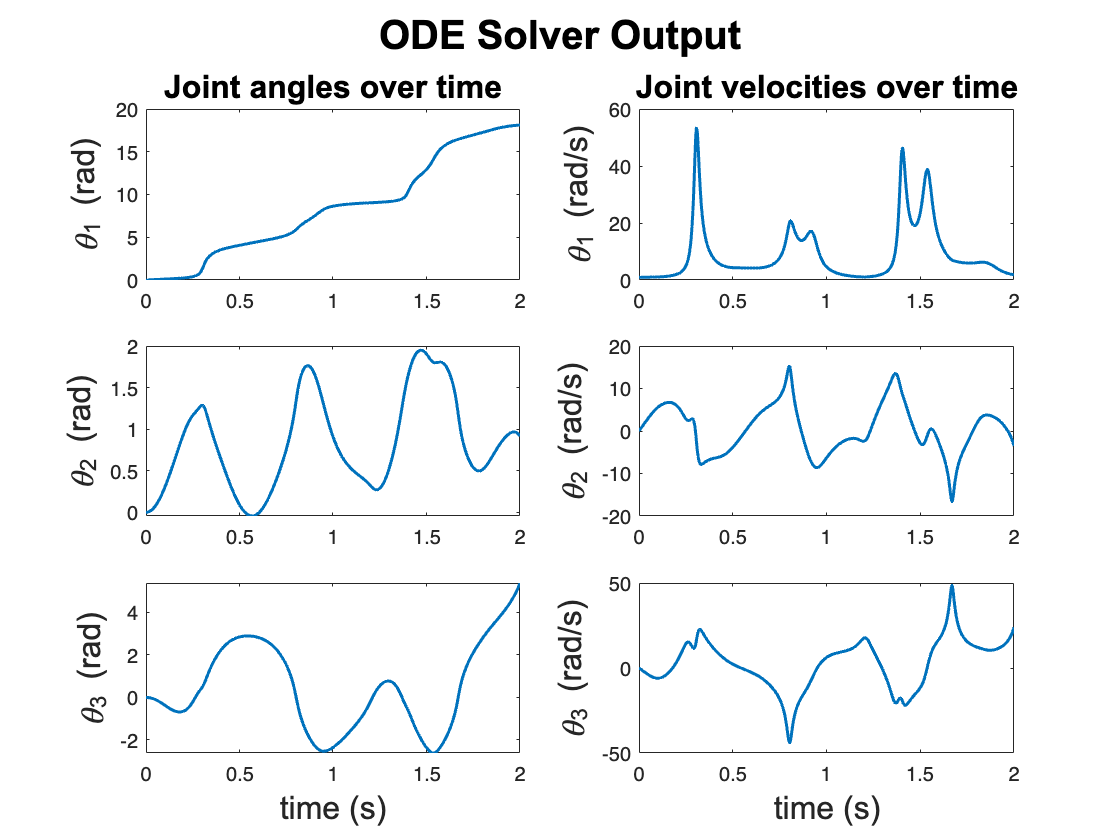

% Plot joint angles and velocities over time
figure;

subplot(3,2,1)
plot(t,x(:,1),'LineWidth',1.5);
ylabel('\theta_1 (rad)','FontSize',16,'FontName','Arial')
title('Joint angles over time','FontSize',16,'FontName','Arial')

subplot(3,2,3)
plot(t,x(:,2),'LineWidth',1.5);
ylabel('\theta_2 (rad)','FontSize',16,'FontName','Arial')

subplot(3,2,5)
plot(t,x(:,3),'LineWidth',1.5);
ylabel('\theta_3 (rad)','FontSize',16,'FontName','Arial')
xlabel('time (s)','FontSize',16,'FontName','Arial')

subplot(3,2,2)
plot(t,x(:,4),'LineWidth',1.5);
ylabel('\theta_1 (rad/s)','FontSize',16,'FontName','Arial')
title('Joint velocities over time','FontSize',16,'FontName','Arial')

subplot(3,2,4)
plot(t,x(:,5),'LineWidth',1.5);
ylabel('\theta_2 (rad/s)','FontSize',16,'FontName','Arial')

subplot(3,2,6)
plot(t,x(:,6),'LineWidth',1.5);
ylabel('\theta_3 (rad/s)','FontSize',16,'FontName','Arial')
xlabel('time (s)','FontSize',16,'FontName','Arial')

sgtitle('ODE Solver Output','FontSize',20,'FontName','Arial','FontWeight','Bold')

## Q2c) Animate robot

anim_3D(t,x,1/24,'HW2_Q2');

## Q2d) Compare to Simulink answer

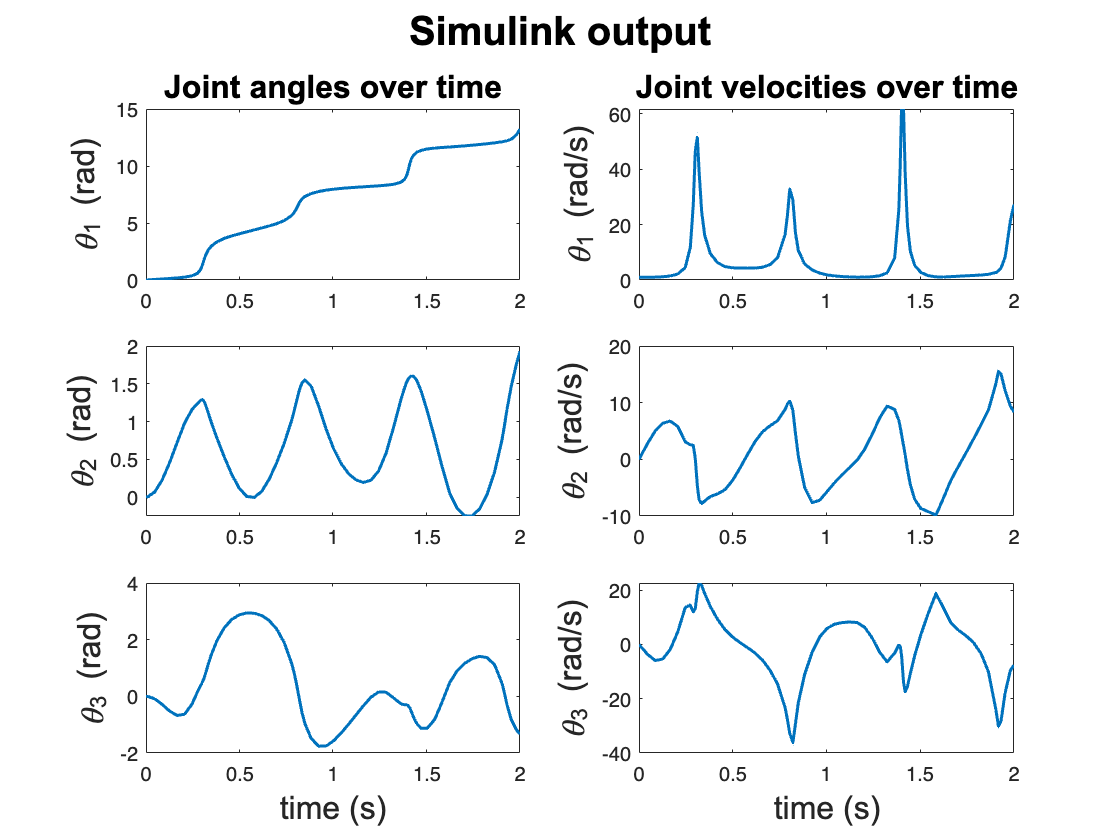

% Run Simulink simulation
out = sim('AME556_HW2_Q2.slx',2);

% Plots of Simulink output
figure;
subplot(3,2,1)
plot(out.tout,out.angle1(:,1),'LineWidth',1.5);
ylabel('\theta_1 (rad)','FontSize',16,'FontName','Arial')
title('Joint angles over time','FontSize',16,'FontName','Arial')

subplot(3,2,3)
plot(out.tout,out.angle2(:,1),'LineWidth',1.5);
ylabel('\theta_2 (rad)','FontSize',16,'FontName','Arial')

subplot(3,2,5)
plot(out.tout,out.angle3(:,1),'LineWidth',1.5);
ylabel('\theta_3 (rad)','FontSize',16,'FontName','Arial')
xlabel('time (s)','FontSize',16,'FontName','Arial')

subplot(3,2,2)
plot(out.tout,out.vel1(:,1),'LineWidth',1.5);
ylabel('\theta_1 (rad/s)','FontSize',16,'FontName','Arial')
title('Joint velocities over time','FontSize',16,'FontName','Arial')

subplot(3,2,4)
plot(out.tout,out.vel2(:,1),'LineWidth',1.5);
ylabel('\theta_2 (rad/s)','FontSize',16,'FontName','Arial')

subplot(3,2,6)
plot(out.tout,out.vel3(:,1),'LineWidth',1.5);
ylabel('\theta_3 (rad/s)','FontSize',16,'FontName','Arial')
xlabel('time (s)','FontSize',16,'FontName','Arial')

sgtitle('Simulink output','FontSize',20,'FontName','Arial','FontWeight','Bold')

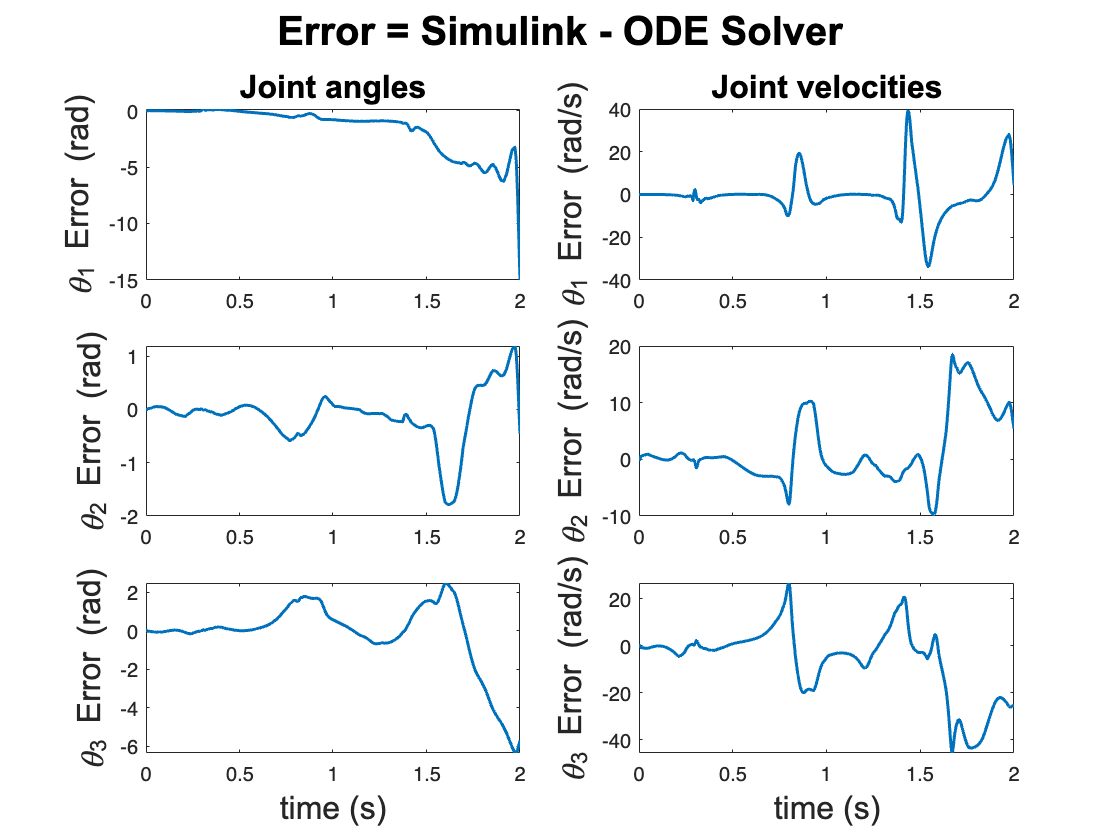


% Calculate errors
resample_angle1 = resample(out.angle1,length(x),length(out.angle1));
resample_angle2 = resample(out.angle2,length(x),length(out.angle2));
resample_angle3 = resample(out.angle3,length(x),length(out.angle3));
resample_vel1 = resample(out.vel1,length(x),length(out.vel1));
resample_vel2 = resample(out.vel2,length(x),length(out.vel2));
resample_vel3 = resample(out.vel3,length(x),length(out.vel3));

e_angle1 = resample_angle1 - x(:,1);
e_angle2 = resample_angle2 - x(:,2);
e_angle3 = resample_angle3 - x(:,3);
e_vel1 = resample_vel1 - x(:,4);
e_vel2 = resample_vel2 - x(:,5);
e_vel3 = resample_vel3 - x(:,6);

figure;
subplot(3,2,1)
plot(t, e_angle1,'LineWidth',1.5);
ylabel('\theta_1 Error (rad)','FontSize',16,'FontName','Arial')
title('Joint angles','FontSize',16,'FontName','Arial')

subplot(3,2,3)
plot(t, e_angle2,'LineWidth',1.5);
ylabel('\theta_2 Error (rad)','FontSize',16,'FontName','Arial')

subplot(3,2,5)
plot(t, e_angle3,'LineWidth',1.5);
ylabel('\theta_3 Error (rad)','FontSize',16,'FontName','Arial')
xlabel('time (s)','FontSize',16,'FontName','Arial')

subplot(3,2,2)
plot(t, e_vel1,'LineWidth',1.5);
ylabel('\theta_1 Error (rad/s)','FontSize',16,'FontName','Arial')
title('Joint velocities','FontSize',16,'FontName','Arial')

subplot(3,2,4)
plot(t, e_vel2,'LineWidth',1.5);
ylabel('\theta_2 Error (rad/s)','FontSize',16,'FontName','Arial')

subplot(3,2,6)
plot(t, e_vel3,'LineWidth',1.5);
ylabel('\theta_3 Error (rad/s)','FontSize',16,'FontName','Arial')
xlabel('time (s)','FontSize',16,'FontName','Arial')

sgtitle('Error = Simulink - ODE Solver','FontSize',20,'FontName','Arial','FontWeight','Bold')

## Q3. 3D quadruped robot

clear;
global params

% Robot parameters
a = 0.15;       % m
b = 0.5;
c = 0.3;
mass = 10;      % kg
g = [0;0;-9.81];

params.a = a;
params.b = b;
params.c = c;
params.mass = mass;
params.g = g;

tspan=[0; 2]; % simulation time (s)

% Moment of inertia equations
Ixb = (1/12)*mass*(a^2+c^2);
Iyb = (1/12)*mass*(a^2+b^2);
Izb = (1/12)*mass*(b^2+c^2);
Ib = [Ixb 0 0; 0 Iyb 0; 0 0 Izb];
params.Ib = Ib;

% Control inputs
gs = 9.81; % scalar
F1b = [0;0;mass*gs/4];
F2b = [0;0;mass*gs/4];
F3b = [0;0;mass*gs/4];
F4b = [0;0;mass*gs/4];
params.F1b = F1b;
params.F2b = F2b;
params.F3b = F3b;
params.F4b = F4b;

% Foot positions
pf1 = [0.25; 0.15; 0];
pf2 = [0.25; -0.15; 0];
pf3 = [-0.25; 0.15; 0];
pf4 = [-0.25; -0.15; 0];
params.pf1 = pf1;
params.pf2 = pf2;
params.pf3 = pf3;
params.pf4 = pf4;

% Initial conditions
p0 = [0.05; 0.05; 0.2];
R0 = eul2rotm([pi/4, pi/8, pi/6]);

params.p0 = p0;
params.R0 = R0;
for ii = 1:9
    if ii < 4
        R0_v(ii,1) = R0(1,ii);
    elseif ii < 7 
        R0_v(ii,1) = R0(2,ii-3);
    else
        R0_v(ii,1) = R0(3,ii-6);
    end
end
v0 = [0; 0; 0];
w0 = [0; 0; 0];
x0 = [p0; R0_v; v0; w0];

[t,x]=ode45(@sys_dynamics_quad,tspan,x0);

## Q3. Plots of quadruped COM and body orientation

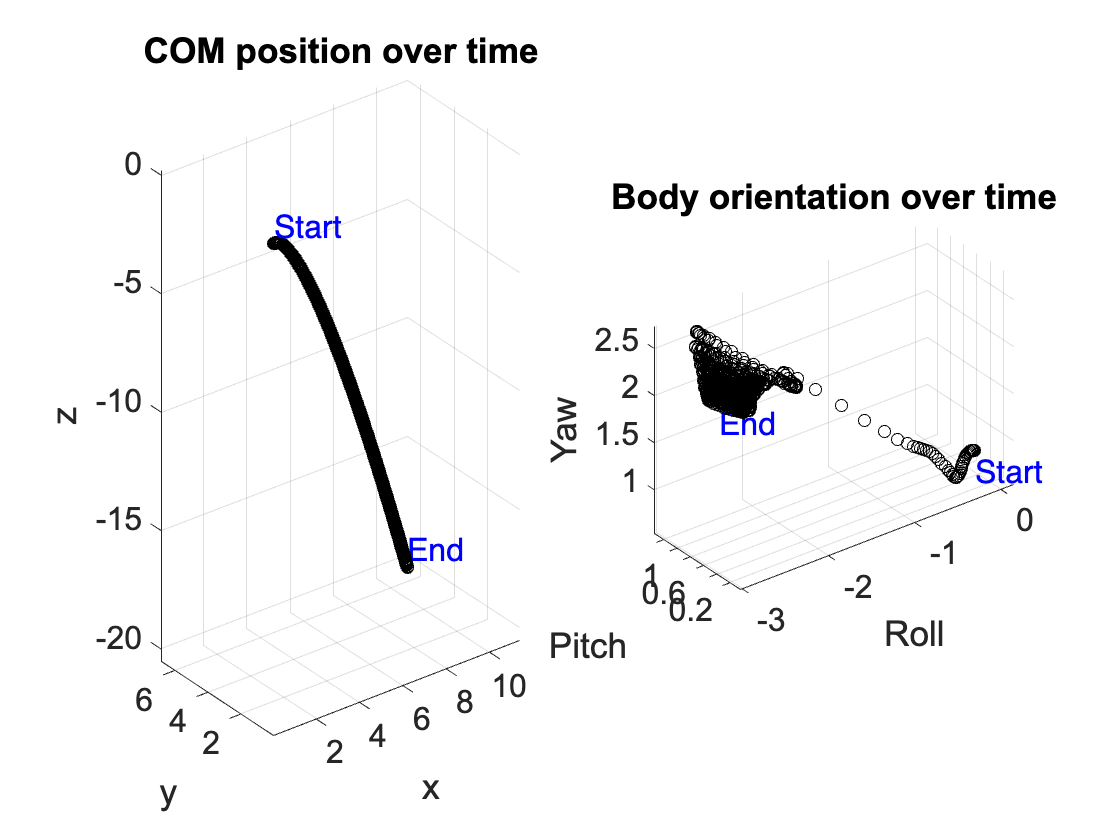

% Plot COM position
figure; hold on;
subplot(1,2,1)
plot3(x(:,1),x(:,2),x(:,3),'ko')

% Add vertices as text
labels = {'Start','End'};
text(x(1,1),x(1,2),x(1,3),labels{1},'VerticalAlignment','bottom','FontSize',16,'Color','b')
text(x(end,1),x(end,2),x(end,3),labels{2},'VerticalAlignment','bottom','FontSize',16,'Color','b')

% Plot settings
xlabel('x')
ylabel('y')
zlabel('z')
view(3)
axis('equal')
grid on

title('COM position over time')
set(gca,'FontName','Arial','FontSize',16)

% Plot body orientation's Euler angles
for ii = 1:length(x)
    clearvars R_plot
    R_plot(1,1:3) = x(ii,4:6);
    R_plot(2,1:3) = x(ii,7:9);
    R_plot(3,1:3) = x(ii,10:12);
    euler(ii,1:3) = rotm2eul(R_plot,'XYZ');
end
subplot(1,2,2); hold on;
plot3(euler(:,1),euler(:,2),euler(:,3),'ko')

% Add vertices as text
labels = {'Start','End'};
text(euler(1,1),euler(1,2),euler(1,3),labels{1},'VerticalAlignment','top','FontSize',16,'Color','b')
text(euler(end,1),euler(end,2),euler(end,3),labels{2},'VerticalAlignment','top','FontSize',16,'Color','b')

% Plot settings
xlabel('Roll')
ylabel('Pitch')
zlabel('Yaw')
view(3)
axis('equal')
grid on

title('Body orientation over time')
set(gca,'FontName','Arial','FontSize',16)

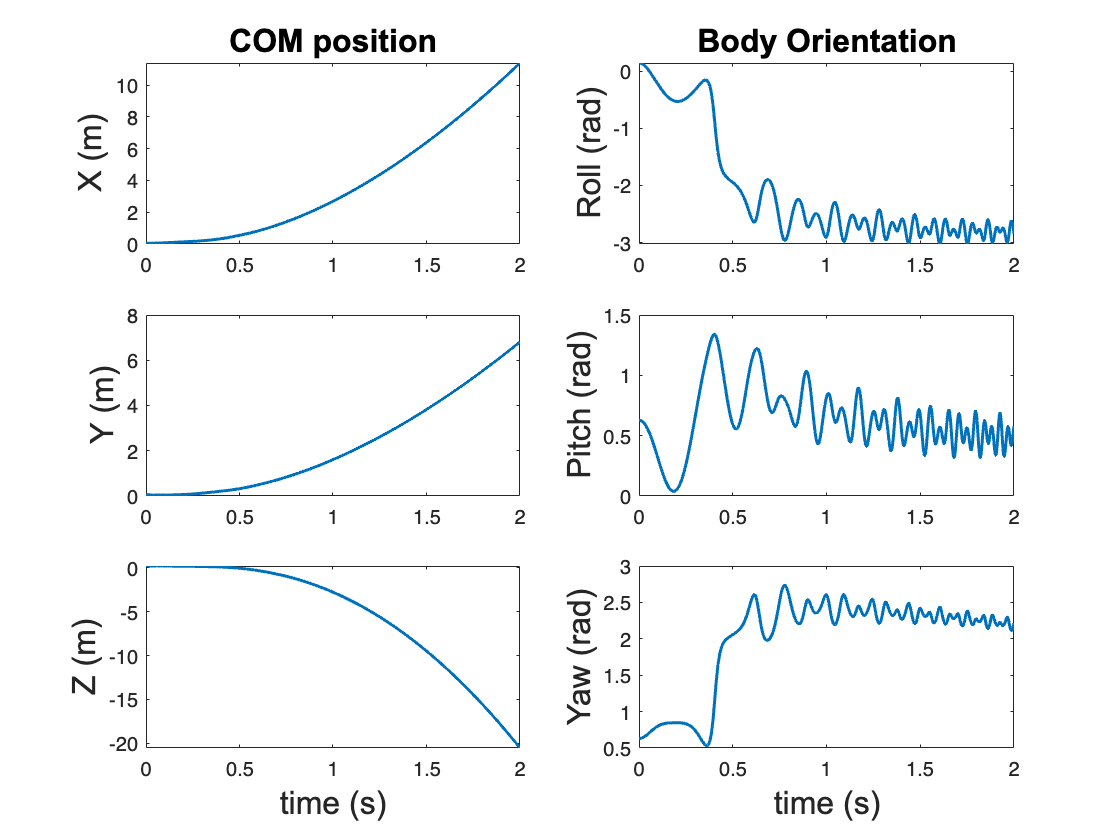


% In 2D
figure;
subplot(3,2,1)
plot(t,x(:,1),'LineWidth',1.5)
ylabel('X (m)','FontSize',16,'FontName','Arial')
title('COM position','FontSize',16,'FontName','Arial','FontWeight','Bold')

subplot(3,2,3)
plot(t,x(:,2),'LineWidth',1.5)
ylabel('Y (m)','FontSize',16,'FontName','Arial')

subplot(3,2,5)
plot(t,x(:,3),'LineWidth',1.5)
ylabel('Z (m)','FontSize',16,'FontName','Arial')
xlabel('time (s)','FontSize',16,'FontName','Arial')

subplot(3,2,2)
plot(t,euler(:,1),'LineWidth',1.5)
ylabel('Roll (rad)','FontSize',16,'FontName','Arial')
title('Body Orientation','FontSize',16,'FontName','Arial','FontWeight','Bold')

subplot(3,2,4)
plot(t,euler(:,2),'LineWidth',1.5)
ylabel('Pitch (rad)','FontSize',16,'FontName','Arial')

subplot(3,2,6)
plot(t,euler(:,3),'LineWidth',1.5)
ylabel('Yaw (rad)','FontSize',16,'FontName','Arial')
xlabel('time (s)','FontSize',16,'FontName','Arial')

## Animate robot motion

anim_3D(t,x,1/24,'HW2_Q3');

## FUNCTIONS

function dx=sys_dynamics_ball(t,x)
    global params
    % Organize values from x input where x = [positions; velocities]
    v(1:2,1) = x(3:4);

    % X and Y accelerations based on F = ma
    ddx(1,1) = -params.c/params.m * norm(v) * v(1);
    ddy(1,1) = -params.g-params.c/params.m * norm(v) * v(2);

    % dx = [velocities; accelerations];
    dx = [v;ddx;ddy];
end

function dx=sys_dynamics_arm(t,x)
    global params

    % Control input
    u=controller_arm(t,x);

    % Organize values from x input where x = [q; q_dot]
    theta2 = x(2);
    theta3 = x(3);
    dtheta1 = x(4);
    dtheta2 = x(5);
    dtheta3 = x(6);

    % First 3 = joint vels (q_dot)
    dx(1:3,1) = [dtheta1; dtheta2; dtheta3];

    % Robot parameters
    a2 = params.a2;
    a3 = params.a3;
    m2 = params.m2;
    m3 = params.m3;

    % D(q) and N(q,q_dot) from eom function (solved earlier)
    D = [(m3*(6*a2^2*cos(2*theta2) + 2*a3^2*cos(2*theta2 + 2*theta3) + 6*a2^2 + 2*a3^2 + 6*a2*a3*cos(2*theta2 + theta3) + 6*a2*a3*cos(theta3)))/12 - (a2^2*m2*(8*sin(theta2)^2 - 8))/24, 0, 0;
         0, (m3*(12*a2^2 + 12*cos(theta3)*a2*a3 + 4*a3^2))/12 + (a2^2*m2)/3, (m3*(4*a3^2 + 6*a2*cos(theta3)*a3))/12;
         0, (m3*(4*a3^2 + 6*a2*cos(theta3)*a3))/12, (a3^2*m3)/3];

    N = [-dtheta2*((m3*(12*dtheta1*sin(2*theta2)*a2^2 + 12*dtheta1*sin(2*theta2 + theta3)*a2*a3 + 4*dtheta1*sin(2*theta2 + 2*theta3)*a3^2))/12 + (2*a2^2*dtheta1*m2*cos(theta2)*sin(theta2))/3) - (dtheta3*m3*(4*a3^2*dtheta1*sin(2*theta2 + 2*theta3) + 6*a2*a3*dtheta1*sin(theta3) + 6*a2*a3*dtheta1*sin(2*theta2 + theta3)))/12;
         (m3*(6*sin(2*theta2)*a2^2*dtheta1^2 + 6*sin(2*theta2 + theta3)*a2*a3*dtheta1^2 + 2*sin(2*theta2 + 2*theta3)*a3^2*dtheta1^2))/12 - (981*m3*((a3*cos(theta2 + theta3))/2 + a2*cos(theta2)))/100 - (981*a2*m2*cos(theta2))/200 - (dtheta3*m3*(12*a2*a3*dtheta2*sin(theta3) + 6*a2*a3*dtheta3*sin(theta3)))/12 + (a2^2*dtheta1^2*m2*cos(theta2)*sin(theta2))/3;
         (m3*(2*a3^2*dtheta1^2*sin(2*theta2 + 2*theta3) + 3*a2*a3*dtheta1^2*sin(2*theta2 + theta3) + 3*a2*a3*dtheta1^2*sin(theta3) + 6*a2*a3*dtheta2^2*sin(theta3) + 6*a2*a3*dtheta2*dtheta3*sin(theta3)))/12 - (981*a3*m3*cos(theta2 + theta3))/200 - (a2*a3*dtheta2*dtheta3*m3*sin(theta3))/2];
    
    % D*q_double_dot + N = tau
    ddq = D\(u-N);

    % Last 3 = joint accels (q_double_dot)
    dx(4:6,1) = ddq;
end

function dx=sys_dynamics_quad(t,x)
    global params

    % Control input
    u=controller_quad(t,x);
    F1b = u(1:3);
    F2b = u(4:6);
    F3b = u(7:9);
    F4b = u(10:12);
    Fb = F1b + F2b + F3b + F4b;

    % Organize values from x input where x = [p; R; dp; wb]
    p = x(1:3);
    R(1,1:3) = x(4:6);
    R(2,1:3) = x(7:9);
    R(3,1:3) = x(10:12);
    dp = x(13:15);
    wb = x(16:18);
    
    % First 3 = linear velocities (dp)
    dx(1:3,1) = dp;

    % Derivative of Rotation matrix dR = R*S(wb)
    S = [0 -wb(3) wb(2);
         wb(3) 0 -wb(1);
         -wb(2) wb(1) 0];
    dR = R*S;

    % Next 9 = dR in 9x1 vector
    dx(4:12,1) = [dR(1,:)'; dR(2,:)'; dR(3,:)'];

    % Linear accelerations (ddp)
    F = R*Fb; % F = R*Fb where Fb = sum of all external force wrt {b}
    ddp = F./params.mass + params.g; % F = ma

    % Next 3 = ddp
    dx(13:15,1) = ddp;
    
    % Angular accelerations (dwb)
    r1b = transpose(R)*(params.pf1 - p); % ri = R*rb where ri = pf-p
    r2b = transpose(R)*(params.pf2 - p);
    r3b = transpose(R)*(params.pf3 - p);
    r4b = transpose(R)*(params.pf4 - p);

    M1b = cross(r1b,F1b);   % M = rXF
    M2b = cross(r2b,F2b);
    M3b = cross(r3b,F3b);
    M4b = cross(r4b,F4b);
    Mb = M1b + M2b + M3b + M4b; % sum of all moments

    dwb = params.Ib\(Mb - cross(wb,params.Ib*wb)); % I*dwb + wb X (I*wb) = Mb

    % Last 3 = dwb
    dx(16:18,1) = dwb;
end

% Q2 controller
function u=controller_arm(t,x)
    global params
    u = params.tau; 
end

% Q3 controller
function u=controller_quad(t,x)
    global params
    u = [params.F1b; params.F2b; params.F3b; params.F4b];
end

% Function to find D(q) and N(q,q_dot) from kinetic and potential energies
function [D,N] = eom(K,P)
    global params
    % Lagrange
    L = K-P;

    % df/dt = df/dq * q_dot + df/dq_dot * q_double_dot

    % f = dL/dq_dot
    f = jacobian(L,params.dq)'; % 3x1 vector

    % D = df/dq_dot
    D = jacobian(f,params.dq); % 3x3 matrix

    % D_dot = df/dq
    dD = jacobian(f,params.q); % 3x3 matrix

    % g = dP/dq
    g = jacobian(P,params.q)'; % 3x1 vector

    % C*q_dot = D_dot * q_dot - dK/dq
    Cqdot = dD*params.dq - jacobian(K,params.q)'; % 3x1 vector

    % N = C*q_dot + g
    N = Cqdot + g; % 3x1 vector
end


function anim(t,x,ts,filename)
    [te,xe]=even_sample(t,x,1/ts);  % evenly sample for video frames
    
    figure(1);
    axes1 = axes;
    
    % Save as a video
    spwriter = VideoWriter(filename,'MPEG-4');
    set(spwriter, 'FrameRate', 1/ts,'Quality',100);
    open(spwriter);
    
    fig1 = figure(1);
    
    % Set limits
    figure_x_limits = [0 3];
    figure_y_limits = [-12 2];
    
    axes1 = axes;
    set(axes1,'XLim',figure_x_limits,'YLim',figure_y_limits);
    set(axes1,'Position',[0 0 1 1]);
    set(axes1,'Color','w');
    
    % Loop through the time and plot each data point at a time
    for k = 1:length(te)
        drawone(axes1, xe(k,:)');
        set(axes1,'XLim',figure_x_limits,'YLim',figure_y_limits);
        drawnow;
        pause(ts);
        frame = getframe(gcf);
        writeVideo(spwriter, frame);
    end
end

function anim_3D(t,x,ts,filename)
    [te,xe]=even_sample(t,x,1/ts); % evenly sample for video frames

    figure;
            
    % Save as a video
    spwriter = VideoWriter(filename,'MPEG-4');
    set(spwriter, 'FrameRate', 1/ts,'Quality',100);
    open(spwriter);
    
    % Set limits
    axes1 = axes;
    if filename == 'HW2_Q2'
        figure_x_limits = [-0.5 0.5];
        figure_y_limits = [-0.5 0.5];
        figure_z_limits = [-0.5 0.5];
        set(axes1,'XLim',figure_x_limits,'YLim',figure_y_limits,'ZLim',figure_z_limits)
    end
    
    % Plot settings
    set(axes1,'Color','w');
    xlabel('x (m)','FontSize',16,'FontName','Arial')
    ylabel('y (m)','FontSize',16,'FontName','Arial')
    zlabel('z (m)','FontSize',16,'FontName','Arial')
    view(3)
    axis('equal')
    grid on
    set(gca,'FontSize',16,'FontName','Arial')
    
    % Loop through the time and plot each data point at a time
    for k = 1:length(te)
        drawone(axes1, xe(k,:)');
        if filename == 'HW2_Q2'
            set(axes1,'XLim',figure_x_limits,'YLim',figure_y_limits,'ZLim',figure_z_limits);
        end
        drawnow;
        pause(ts);
        frame = getframe(gcf);
        writeVideo(spwriter, frame);
    end
end

function [Et, Ex] = even_sample(t, x, Fs)
    % CONVERTS A RANDOMLY SAMPLED SIGNAL SET INTO AN EVENLY SAMPLED
    % SIGNAL SET (by interpolation)
    % Obtain the process related parameters
    N = size(x, 2);    % number of signals to be interpolated
    M = size(t, 1);    % Number of samples provided
    t0 = t(1,1);       % Initial time
    tf = t(M,1);       % Final time
    EM = (tf-t0)*Fs;   % Number of samples in the evenly sampled case with
                       % the specified sampling frequency
    Et = linspace(t0, tf, EM)';
    
    % Using linear interpolation (used to be cubic spline interpolation)
    % and re-sample each signal to obtain the evenly sampled forms
    for s = 1:N
        Ex(:,s) = interp1(t(:,1), x(:,s), Et(:,1)); 
    end
end

function drawone(parent, x)
    global params
    % Delete existing plot
    tem = get(parent,'Children');
    delete(tem);

    % Draw the robot at the current frame
    if length(x) == 2 % Q1
        % Position of ball
        px = x(1);
        py = x(2);
        p = [px; py];
             
        % Plot ball position
        plot(p(1),p(2),'bo','MarkerSize',8,'MarkerFaceColor','b');

    elseif length(x) == 6 % Q2
        hold on;
        
        % Get joint positions
        theta1 = x(1);
        theta2 = x(2);
        theta3 = x(3);

        % Sub joint positions into transformation matrices
        H01_sub = simplify(subs(params.H01));
        H12_sub = simplify(subs(params.H12));
        H23_sub = simplify(subs(params.H23));
    
        % Pull endpoint positions from each homogeneous transf. matrix
        % wrt world frame {0}
        O0 = [0;0;0];                       % Fixed base O0
        O1 = H01_sub(1:3,end);              % Position of 01
        H02 = simplify(H01_sub*H12_sub);    % Get in world frame {0}
        O2 = H02(1:3,end);                  % Position of O2
        H03 = simplify(H02*H23_sub);        % Get in world frame {0}
        O3 = H03(1:3,end);                  % Position of O3

        % Plot each link based on endpoint positions (and origin O0)
        plot3([O0(1) O1(1)],[O0(2) O1(2)],[O0(3) O1(3)],'-ob','LineWidth',1.5)
        plot3([O1(1) O2(1)],[O1(2) O2(2)],[O1(3) O2(3)],'-og','LineWidth',1.5)
        plot3([O2(1) O3(1)],[O2(2) O3(2)],[O2(3) O3(3)],'-or','LineWidth',1.5)

        % Add axes for {1} to help visualize rotation
        rotated_x = H01_sub(1:3,1:3)*[0.05; 0; 0];
        rotated_y = H01_sub(1:3,1:3)*[0; 0.05; 0];

        plot3([0 rotated_x(1)],[0 rotated_x(2)],[0.1 0.1],'k-')
        plot3([0 rotated_y(1)],[0 rotated_y(2)],[0.1 0.1],'k-')
        plot3([0 0],[0 0],[0.1 0.15],'k-')

    elseif length(x) == 18 % Q3
        hold on;
        % COM position
        px = x(1);
        py = x(2);
        pz = x(3);
        p = [px;py;pz];

        % Four points representing feet
        plot3(params.pf1(1),params.pf1(2),params.pf1(3),'ok','MarkerFaceColor','k','MarkerSize',10)
        plot3(params.pf2(1),params.pf2(2),params.pf2(3),'ok','MarkerFaceColor','k','MarkerSize',10)
        plot3(params.pf3(1),params.pf3(2),params.pf3(3),'ok','MarkerFaceColor','k','MarkerSize',10)
        plot3(params.pf4(1),params.pf4(2),params.pf4(3),'ok','MarkerFaceColor','k','MarkerSize',10)
        
        % Four vectors for control inputs
        R(1,1:3) = x(4:6); % rotation matrix
        R(2,1:3) = x(7:9);
        R(3,1:3) = x(10:12);

        F1 = R*params.F1b; % get force into world frame
        F2 = R*params.F2b;
        F3 = R*params.F3b;
        F4 = R*params.F4b;

        % Plot normalized vectors
        plot3([params.pf1(1) params.pf1(1)+F1(1)/100],[params.pf1(2) params.pf1(2)+F1(2)/100],[params.pf1(3) params.pf1(3)+F1(3)/100],'-r')
        plot3([params.pf2(1) params.pf2(1)+F2(1)/100],[params.pf2(2) params.pf2(2)+F2(2)/100],[params.pf2(3) params.pf2(3)+F2(3)/100],'-r')
        plot3([params.pf3(1) params.pf3(1)+F3(1)/100],[params.pf3(2) params.pf3(2)+F3(2)/100],[params.pf3(3) params.pf3(3)+F3(3)/100],'-r')
        plot3([params.pf4(1) params.pf4(1)+F4(1)/100],[params.pf4(2) params.pf4(2)+F4(2)/100],[params.pf4(3) params.pf4(3)+F4(3)/100],'-r')

        % Define robot body vertices in body frame
        v1b = [-params.b/2; -params.c/2; params.a/2];
        v2b = v1b + [0;params.c;0];
        v3b = v1b + [0;0;-params.a];
        v4b = v1b + [0;params.c;-params.a];
        v5b = v1b + [params.b;0;0];
        v6b = v1b + [params.b;params.c;0];
        v7b = v1b + [params.b;0;-params.a];
        v8b = v1b + [params.b;params.c;-params.a];

        % Transform robot body vertices into world frame
        v1 = R*v1b + p;
        v2 = R*v2b + p;
        v3 = R*v3b + p;
        v4 = R*v4b + p;
        v5 = R*v5b + p;
        v6 = R*v6b + p;
        v7 = R*v7b + p;
        v8 = R*v8b + p;

        % Plot robot body box lines
        line1 = [v1 v2];
        plot3(line1(1,:),line1(2,:),line1(3,:),'k-')
        line2 = [v1 v3];
        plot3(line2(1,:),line2(2,:),line2(3,:),'k-')
        line3 = [v2 v4];
        plot3(line3(1,:),line3(2,:),line3(3,:),'k-')
        line4 = [v3 v4];
        plot3(line4(1,:),line4(2,:),line4(3,:),'k-')

        line1 = [v5 v6];
        plot3(line1(1,:),line1(2,:),line1(3,:),'k-')
        line2 = [v5 v7];
        plot3(line2(1,:),line2(2,:),line2(3,:),'k-')
        line3 = [v6 v8];
        plot3(line3(1,:),line3(2,:),line3(3,:),'k-')
        line4 = [v7 v8];
        plot3(line4(1,:),line4(2,:),line4(3,:),'k-')

        line1 = [v1 v5];
        plot3(line1(1,:),line1(2,:),line1(3,:),'k-')
        line2 = [v2 v6];
        plot3(line2(1,:),line2(2,:),line2(3,:),'k-')
        line3 = [v3 v7];
        plot3(line3(1,:),line3(2,:),line3(3,:),'k-')
        line4 = [v4 v8];
        plot3(line4(1,:),line4(2,:),line4(3,:),'k-')

        % Plot COM position
        plot3(p(1),p(2),p(3),'bo','MarkerSize',8,'MarkerFaceColor','b');  
    end
end